M = 5;
frequency = [4 8];
ks = 0.5;
variance = 0.02;
samples = 1000;
E_oil = 3;
E_air =1;
temp = 20;
salinity = 35;
theta = 0;
tmin = 0;
thickness_step = 0.1;
tmax= 10;




probability_of_detection demo

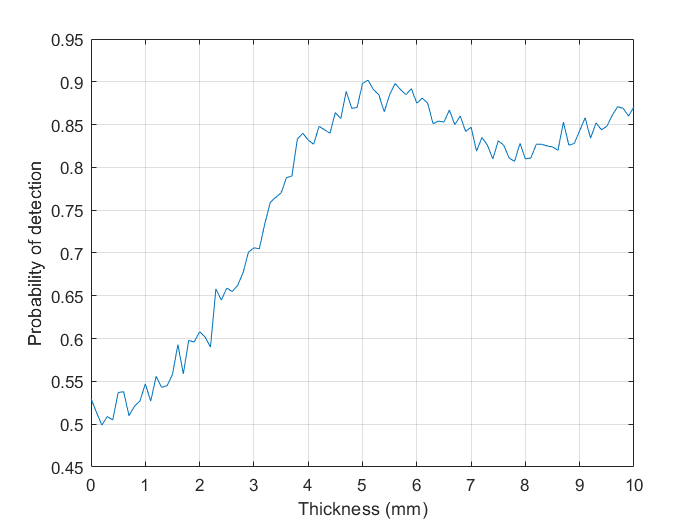



%% Probability plot
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

thickness = tmin:thickness_step:tmax;
probability = probability_of_detection(M, frequency, ks, thickness_step, variance, samples, E_oil, E_air, temp, salinity, theta, tmin, tmax);
plot(thickness, probability);
grid on;
xlabel("Thickness (mm)");
ylabel("Probability of detection");


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




Detection_probability demo

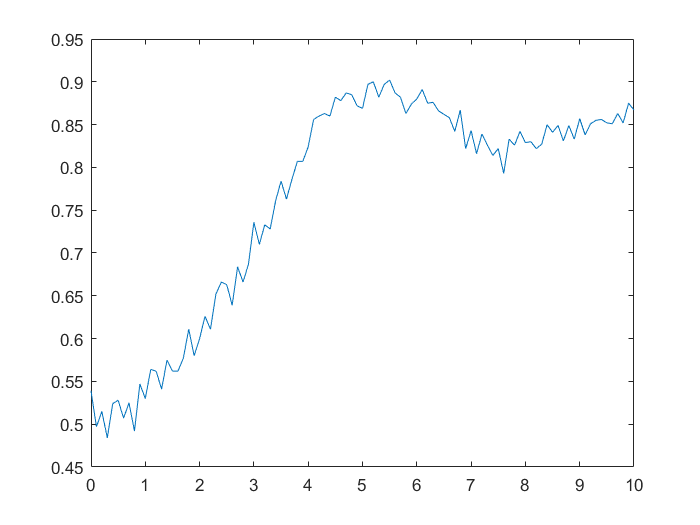

figure;
prob = double.empty;

for i = tmin:thickness_step:tmax    
    oil = 0;
    for j = 0:samples
        desired_reflectivity  = reflectivity(frequency, i, ks, E_oil, E_air, temp, salinity, theta);
        
        oil_found = Detection_probability(desired_reflectivity, i, M, frequency, ks, variance, E_oil, E_air, temp, salinity, theta, tmin, thickness_step, tmax);
       
        if oil_found >= 1
            oil = oil + 1;
        end
    end
    
    prob(length(prob) + 1) = oil/samples;  
end

plot(thickness, prob);